x=imread("Virat.jpg");
x=rgb2gray(x);
x=im2double(x);
y=imnoise(x,'gaussian',0.9);
filt=ones(5,5)/25;
conv=conv2(y,filt,'same')

conv =    0.360000000000000   0.478773910047823   0.598773910047823   0.593459735962204   0.593459735962204   0.592497336988088   0.593723426940265   0.593723426940265   0.599037601025884   0.599037601025884   0.600000000000000   0.600000000000000   0.600000000000000   0.597266389260201   0.597266389260201   0.597266389260201   0.597266389260201   0.597217060918163   0.596357864631472   0.596357864631472   0.596357864631472   0.596357864631472   0.595684678263522   0.599277485290011   0.599277485290011   0.599277485290012   0.599277485290011   0.600000000000000   0.600000000000000   0.599491276388538   0.599491276388538   0.599491276388538   0.599491276388538   0.599491276388538   0.600000000000000   0.600000000000000   0.600000000000000   0.594327606698345   0.594327606698345   0.594305857303872   0.594305857303872   0.594305857303872   0.599105462908878   0.596700042451493   0.596721791845965   0.591209092503313   0.591209092503313   0.592081880199962   0.594487300657347   0.59312842

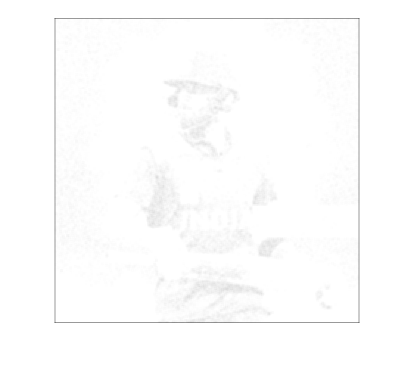

imshow(conv)

ps=psnr(x,y)

ps =    3.758415073810877


ps1=psnr(conv,x)

ps1 =    3.813795983197600


[U S V]= svd(x)

U =   -0.026724207019030  -0.026959835918757   0.017673999177626  -0.051104140404376   0.054674354148900   0.004964531044851  -0.013332230894899  -0.011336501251454   0.070843422313710   0.017084677136920   0.039879901970156  -0.026233088733858  -0.088392802984400   0.028808097851208  -0.068026781880113   0.014245261074503   0.001094899009627   0.015464414716778  -0.037435836300559  -0.017223645380952   0.002561556080704   0.036765850565814  -0.023649798820024  -0.024077208833670   0.008205079993712   0.012145257409787  -0.017080511867664  -0.037447726537583   0.002100519884139   0.006394313581314   0.039192107515248  -0.001529659409292   0.032143092308322   0.015566850452918  -0.005370257451729   0.007098059547087  -0.009949222104610  -0.034740514107934  -0.002774565482391   0.003566942889546  -0.013317063477086  -0.004224079361830   0.000531039521948  -0.009009824394126   0.013285484582529   0.026674866400982   0.001908919545930   0.011951234511113  -0.001681481981169   0.00571256003

S = 1.0e+02 *

   2.114139294025004                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0     

V =   -0.027166902556130   0.061657801126514   0.026754267767976  -0.048647790236225   0.004346346236860  -0.005461037556051   0.020182801190577  -0.044231129282643   0.001507197224388  -0.008622550392370  -0.002296541822245   0.004625072373453  -0.005936716437747   0.003331176632450  -0.003279336953926   0.029980266525837  -0.018858184666021   0.001474953962587  -0.009787583586256  -0.001834973302355   0.022446312966521  -0.001073180461709  -0.008699487580742   0.012020827936630  -0.004959225780511  -0.012238096510678  -0.010041955208564   0.016559529060233   0.016432732677752  -0.002615462099797   0.018365835025371  -0.011754290191598   0.001415675142766  -0.003232546996250   0.014818245471068  -0.008731145188920   0.001168596430723  -0.025114408027984   0.013962792761632  -0.011474718048304   0.002130750215802  -0.003581819042096   0.001138310353682   0.007366792679029  -0.007559918232981   0.009873700288848  -0.014106457931088  -0.005121547187793   0.014985224060662   0.00964180439

sum=zeros(512,512)

sum =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

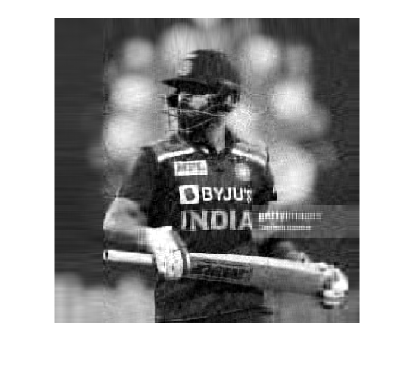

for i=1:30
    sum=sum+U(:,i)*S(i,i)*V(:,i)';
imshow(sum)
end

psnr(sum,x)

ans =   25.393425031755008


x1=imresize(x,0.5)

x1 =    0.196078431372549   0.195904660692402   0.197929831112132   0.199973132563572   0.199933639227175   0.200003709980086   0.200070429783241   0.200082696652880   0.198408598058364   0.197093709309896   0.196437521541820   0.197880883310355   0.197376146503523   0.201541018018536   0.195311482747396   0.195397949218750   0.196665804993873   0.194209977692249   0.199950274299173   0.203241086473652   0.196791405771293   0.199649347043505   0.195276058421415   0.197796271829044   0.200205185834099   0.200025132123162   0.199843941482843   0.197807282092524   0.202192717907475   0.200156058517157   0.199996230181526   0.199888999789369   0.198081760780484   0.199028284409467   0.201255828259038   0.200244858685662   0.198678529028799   0.207050099092371   0.198636103611366   0.195738788679534   0.196225334616268   0.199770340265012   0.203037875306373   0.203394691616881   0.199593817018995   0.203327193914675   0.200506591796875   0.204810108857996   0.207893281824449   0.2070040833

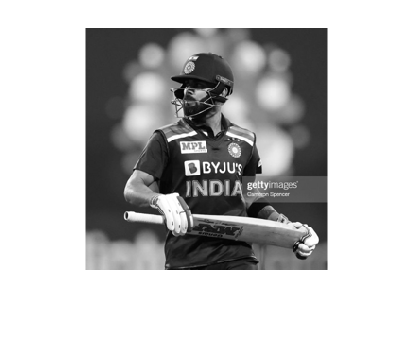

imshow(x1)